clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

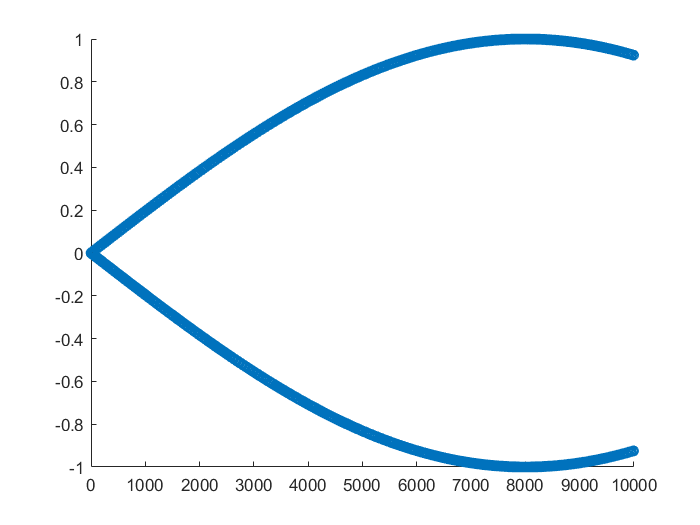

initial_0 = [1 0 0 0 0 0]';
initial = ham_evolve(sigmax+sigmax^2,initial_0,pi/2);
%initial = initial_0;
a=0.005;
ham1 = +a*sigmax+1*sigmaz-100*sigmaz^2;
ham2 = 1*sigmax+1*sigmax^2;
timelist = ([0:0.2:10000].*pi+0.1*pi)/sqrt(a^2+1);
for i = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(i));
    final_state(:,i) = ham_evolve(ham2,precess_state,pi/2);
    %final_state(:,i) = precess_state;
end
pop_state = abs(final_state).^2;

%plot(timelist,pop_state(1,:));
%ylim([0.5 1]);
%plot(timelist,pop_state(6,:));
%ylim([-0.1 0.3]);
scatter(timelist/pi,(pop_state(1,:)-pop_state(6,:))./(pop_state(1,:)+pop_state(6,:)));
%xlim([2000 2010]);
ylim([-1 1]);

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end